# Practice Programming Assignment

In this problem, we'll use the example of writing a function to create a rotation matrix to show how to complete programming assignments. This is an ungraded problem and is optional. 

Rotation matrices are widely used in many fields, including robotics. Our task here is to write a function that accepts an angle in radians (as a scalar value) and returns a 3x3 matrix for the rotation matrix about the **z-axis**. The formula for is given by:


$$R_z =\left\lbrack \begin{array}{ccc}
\cos \left(\phi \right) & -\sin \left(\phi \right) & 0\\
\sin \left(\phi \right) & \cos \left(\phi \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$
   

Below is the function definition for `zrot`. Complete the function to so that it returns the matrix `Rz`. The functions takes a single input, `phi`, that is the angle of rotation in *radians*.

You may write any code in the "Code to call your function" to test your function. In all problems, we will prepopulate this code box with code you can use. In this example, we provide code to rotate and plot a vector using your `zrot` function. Notice that you can Reset this code box separately from the main function code box, so feel free to delete the pre-populated code and try things out. You may find this particularly useful when debugging code in later examples.

When you think you're done, press Submit to see your results.

% This code will run without modification as long as your function returns an 3x3 matrix.

% Create a vector to rotate and choose an angle
% Try out multiple vectors
vec = [1; 0; 0]; % do not change the name if you want to use the visualization code below.
phi = pi/4;

% Create the rotation matrix and apply it to the vector
Rz = zrot(phi)

Rz =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


rotVec = Rz*vec

rotVec =     0.7071
    0.7071
         0


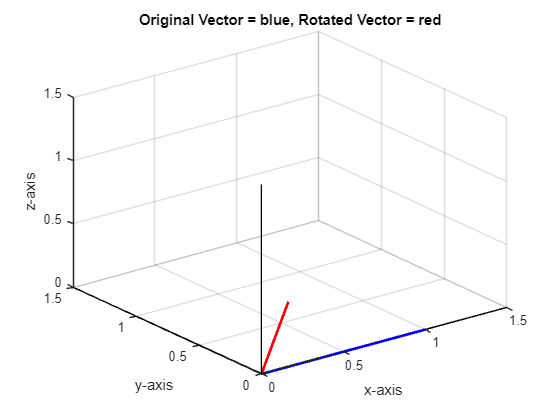


% Visualize the rotation
plot3([0, 1.5], [0, 0], [0, 0], 'k') % x-axis
hold on % This command allows us to put multiple lines on the same axes
plot3([0, 0], [0, 1.5], [0, 0], 'k') % y-axis
plot3([0, 0], [0, 0], [0, 1.5], 'k') % z-axis
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
% Plot the original vector
plot3([0, vec(1)], [0, vec(2)], [0, vec(3)], 'b', 'LineWidth', 2);

% Plot the rotated vector
plot3([0, rotVec(1)], [0, rotVec(2)], [0, rotVec(3)], 'r', 'LineWidth', 2);
title('Original Vector = blue, Rotated Vector = red')
grid on;

function Rz = zrot( phi )
    Rz = [cos(phi) -sin(phi) 0; sin(phi) cos(phi) 0; 0 0 1];
end